% MATLAB script for PFR PET polymerization with film thickness-based km
clear; clc;

% Constants
R = 1.987; % cal/mol-K
T = 230 + 273.15; % K (215°C)
k1 = 3.4e6 * exp(-18500 / (R * T)); % L/mol-min (R1, R8)
k2 = 8.32e7 * exp(-29800 / (R * T)); % min^-1 (R2)
k3 = 83.2e6 * exp(-29800 / (R * T)); % L/mol-min (R3)
k4 = 83.2e6 * exp(-29800 / (R * T)); % L/mol-min (R4)
k5 = 2.08e6 * exp(-17600 / (R * T)); % L/mol-min (R5)
k6 = 2.08e6 * exp(-17600 / (R * T)); % L/mol-min (R6)
k7 = 1.3e11 * exp(-37800 / (R * T)); % min^-1 (R7)
k8 = k1; % R8 same as R1
K1 = 0.5; % Equilibrium constant (R1)
K5 = 2.5; % Equilibrium constant (R5)
K6 = 1.25; % Equilibrium constant (R6)
L = 8.0; % m (reactor length)
De = 6.174e6 * exp(-38400 / (R * T)); % m^2/min (EG diffusivity)
delta = 0.000000005; % m (film thickness = 1 mm)
km = De / delta; % min^-1 (mass transfer coefficient)
E_int = 1e-6; % mol/L (interfacial EG concentration)
W_int = 1e-6; % mol/L (interfacial water concentration)
A_int = 1e-6; % mol/L (interfacial acetaldehyde concentration)
G_int = 1e-6; % mol/L (interfacial DEG concentration)
A_cross = 25 * pi * 1e-2; % m^2 (cross-sectional area)

% Reactor volume
V_reactor = A_cross * L; % m^3

% Calculate volumetric flow rate (m^3/min)
Q = 0.00219; % m^3/min

% Calculate residence time (min)
tau = V_reactor / Q; % min

v = Q / A_cross; % m/min

% Hardcoded initial conditions (mol/L)
DP_input = 4.44;      % Desired input Degree of Polymerization
P_h0 = 0.8874;          % Initial BHET concentration (mol/L)
P_a0 = 0.114;          % Initial acid end group concentration (mol/L)
E_0 = 0.00997;         % Initial ethylene glycol concentration (mol/L)
P_v0 = 0;             % Initial vinyl end group concentration (mol/L)
P_g0 = 0;             % Initial DEG in chain (mol/L)
W_0 = 0.0229;         % Initial water concentration (mol/L)
A_0 = 0;              % Initial acetaldehyde concentration (mol/L)
G_0 = 0;              % Initial free DEG concentration (mol/L)

% Calculate P_0 to match DP_input using DP = (P + Ph) / (E/2 + Pa)
P_0 = DP_input * (E_0 / 2 + P_a0) - P_h0;

% Verify initial DP
DP_initial_calc = (P_0 + P_h0) / (E_0 / 2 + P_a0);
fprintf('Calculated Initial DP from concentrations: %.2f\n', DP_initial_calc);

Calculated Initial DP from concentrations: 4.44


fprintf('Calculated km based on 1 mm film thickness: %.4e min^-1\n', km);

Calculated km based on 1 mm film thickness: 2.5744e-02 min^-1



% ODE system (tracking P, Ph, Pa, Pv, Pg, E, W, A, G)
dCdz = @(z, C) [
    (k1 * (C(2)^2 - 4 * C(1) * C(6) / K1) + k6 * (C(3) * C(2) - 2 * C(1) * C(7) / K6) - ...
     k7 * C(1) + k8 * C(4) * C(2)) / v; % dP/dz
    (-2 * k1 * (C(2)^2 - 4 * C(1) * C(6) / K1) - k2 * C(2) - 2 * k3 * C(2) * C(6) - ...
     2 * k4 * C(2)^2 + k5 * (2 * C(3) * C(6) - C(2) * C(7) / K5) - k6 * (C(3) * C(2) - 2 * C(1) * C(7) / K6) - ...
     k8 * C(4) * C(2)) / v; % dPh/dz
    (k2 * C(2) + k3 * C(2) * C(6) + k4 * C(2)^2 - k5 * (2 * C(3) * C(6) - C(2) * C(7) / K5) - ...
     k6 * (C(3) * C(2) - 2 * C(1) * C(7) / K6) + k7 * C(1)) / v; % dPa/dz
    (k7 * C(1) - k8 * C(4) * C(2)) / v; % dPv/dz
    (k4 * C(2)^2) / v; % dPg/dz
    (-km * (C(6) - E_int) + k1 * (C(2)^2 - 4 * C(1) * C(6) / K1) - k3 * C(2) * C(6) - ...
     k5 * (2 * C(3) * C(6) - C(2) * C(7) / K5)) / v; % dE/dz
    (-km * (C(7) - W_int) + k5 * (2 * C(3) * C(6) - C(2) * C(7) / K5) + ...
     k6 * (C(3) * C(2) - 2 * C(1) * C(7) / K6)) / v; % dW/dz
    (-km * (C(8) - A_int) + k2 * C(2) + k8 * C(4) * C(2)) / v; % dA/dz
    (-km * (C(9) - G_int) + k3 * C(2) * C(6)) / v % dG/dz
];

% Solve
zspan = [0 L];
C0 = [P_0; P_h0; P_a0; P_v0; P_g0; E_0; W_0; A_0; G_0];
[z, C] = ode45(dCdz, zspan, C0);

% Calculate DP along the reactor
DP = (C(:,1) + C(:,2)) ./ (C(:,6) / 2 + C(:,3));

% Output concentrations (at z = L)
P_out = C(end, 1);    % PET (diester)
Ph_out = C(end, 2);   % BHET
Pa_out = C(end, 3);   % Acid end groups
Pv_out = C(end, 4);   % Vinyl end groups
Pg_out = C(end, 5);   % DEG in chain
E_out = C(end, 6);    % Ethylene glycol
W_out = C(end, 7);    % Water
A_out = C(end, 8);    % Acetaldehyde
G_out = C(end, 9);    % Free DEG

% Calculate volumetric flow rate (m^3/min)
Q = 0.00219; % m^3/min

% Calculate residence time (min)
tau = V_reactor / Q; % min

% Calculate molar flow rates (mol/min)
F_P_out = P_out * Q;   % PET
F_Ph_out = Ph_out * Q; % BHET
F_Pa_out = Pa_out * Q; % Acid end groups
F_Pv_out = Pv_out * Q; % Vinyl end groups
F_Pg_out = Pg_out * Q; % DEG in chain
F_E_out = E_out * Q;   % Ethylene glycol
F_W_out = W_out * Q;   % Water
F_A_out = A_out * Q;   % Acetaldehyde
F_G_out = G_out * Q;   % Free DEG

% Output DP
DP_output = DP(end);

% Display results
fprintf('Reactor Volume: %.4f m^3 (%.2f L)\n', V_reactor, V_reactor * 1000);

Reactor Volume: 6.2832 m^3 (6283.19 L)


fprintf('Volumetric Flow Rate: %.4e m^3/min (%.2f L/min)\n', Q, Q * 1000);

Volumetric Flow Rate: 2.1900e-03 m^3/min (2.19 L/min)


fprintf('Residence Time: %.2f min\n', tau);

Residence Time: 2869.03 min


fprintf('Input DP (z = 0 m): %.2f\n', DP_input);

Input DP (z = 0 m): 4.44


fprintf('Output DP (z = %.1f m): %.2f\n', L, DP_output);

Output DP (z = 8.0 m): 64.59


fprintf('Output Concentrations (mol/L):\n');

Output Concentrations (mol/L):


fprintf('  PET (P) = %.4e\n', P_out);

  PET (P) = 1.3482e-01


fprintf('  BHET (Ph) = %.4e\n', Ph_out);

  BHET (Ph) = 1.0210e-02


fprintf('  Pa (acid) = %.4e\n', Pa_out);

  Pa (acid) = 2.2174e-03


fprintf('  Pv (vinyl) = %.4e\n', Pv_out);

  Pv (vinyl) = 9.5795e-04


fprintf('  Pg (DEG in chain) = %.4e\n', Pg_out);

  Pg (DEG in chain) = 1.3233e-04


fprintf('  E (EG) = %.4e\n', E_out);

  E (EG) = 5.6316e-05


fprintf('  W (water) = %.4e\n', W_out);

  W (water) = 3.0887e-05


fprintf('  A (acetaldehyde) = %.4e\n', A_out);

  A (acetaldehyde) = 1.6685e-05


fprintf('  G (free DEG) = %.4e\n', G_out);

  G (free DEG) = 1.0002e-06


fprintf('Output Molar Flow Rates (mol/min):\n');

Output Molar Flow Rates (mol/min):


fprintf('  PET (P) = %.4e\n', F_P_out);

  PET (P) = 2.9525e-04


fprintf('  BHET (Ph) = %.4e\n', F_Ph_out);

  BHET (Ph) = 2.2360e-05


fprintf('  Pa (acid) = %.4e\n', F_Pa_out);

  Pa (acid) = 4.8560e-06


fprintf('  Pv (vinyl) = %.4e\n', F_Pv_out);

  Pv (vinyl) = 2.0979e-06


fprintf('  Pg (DEG in chain) = %.4e\n', F_Pg_out);

  Pg (DEG in chain) = 2.8981e-07


fprintf('  E (EG) = %.4e\n', F_E_out);

  E (EG) = 1.2333e-07


fprintf('  W (water) = %.4e\n', F_W_out);

  W (water) = 6.7643e-08


fprintf('  A (acetaldehyde) = %.4e\n', F_A_out);

  A (acetaldehyde) = 3.6539e-08


fprintf('  G (free DEG) = %.4e\n', F_G_out);

  G (free DEG) = 2.1905e-09


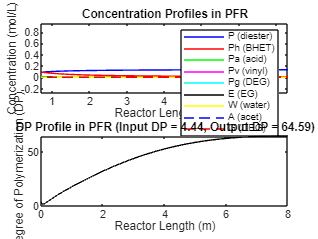


% Plot
figure;
subplot(2,1,1);
plot(z, C(:,1), 'b-', z, C(:,2), 'r-', z, C(:,3), 'g-', z, C(:,4), 'm-', z, C(:,5), 'c-', ...
     z, C(:,6), 'k-', z, C(:,7), 'y-', z, C(:,8), 'b--', z, C(:,9), 'r--');
legend('P (diester)', 'Ph (BHET)', 'Pa (acid)', 'Pv (vinyl)', 'Pg (DEG)', 'E (EG)', 'W (water)', 'A (acet)', 'G (DEG)');
xlabel('Reactor Length (m)');
ylabel('Concentration (mol/L)');
title('Concentration Profiles in PFR');

subplot(2,1,2);
plot(z, DP, 'k-');
xlabel('Reactor Length (m)');
ylabel('Degree of Polymerization (DP)');
title(sprintf('DP Profile in PFR (Input DP = %.2f, Output DP = %.2f)', DP_input, DP_output));